**Instructions on what to turn in: **

Download the folder lab3files to your machine. Inside you will find the following files: 

- lab3_lastname.mlx (rename this file to include your last name)

- newton.m (you will need this code to work on Problem 1) 

What you will need to turn in on Canvas. Upload the following 2 files:

- lab3_lastname.pdf  (instructions on how to generate this below)

- lab3_lastname.zip (a zip folder containing newton.m, secant.m, lab3_lastname.mlx)

How to generate lab3_lastname.pdf. 

Once you have completed all the parts of the assignment and are satisfied with your work, go to View in the top bar and click Output Inline - this makes it so that the grader can easily follow your work. Run lab3_lastname.mlx one more time then go to Live Editor and click Export then choose PDF. A pdf file with the same name as the Live script will be generated with answers to all the parts. 

**Specific instructions for the assignment:**

To make your work easy to grade, please suppress all outputs except for the parts that explictly say not to suppress output. This is most important for any functions you develop. Please make sure everything runs.  

**Problem 1**

**a)** Consider the function $f(x) = e^{\sin^3x} + x^6 - 2x^4 - x^3 - 1$ on the interval $[-2,2]$. Define an anonymous function for $f(x)$ that can take vector input 

f = @(x) exp(sin(x).^3) + x.^6 - 2*x.^4 - x.^3 - 1;

**b)** Plot this function on the interval $[-2,2]$ using 100 evenly spaced points and identify how many roots are present. 

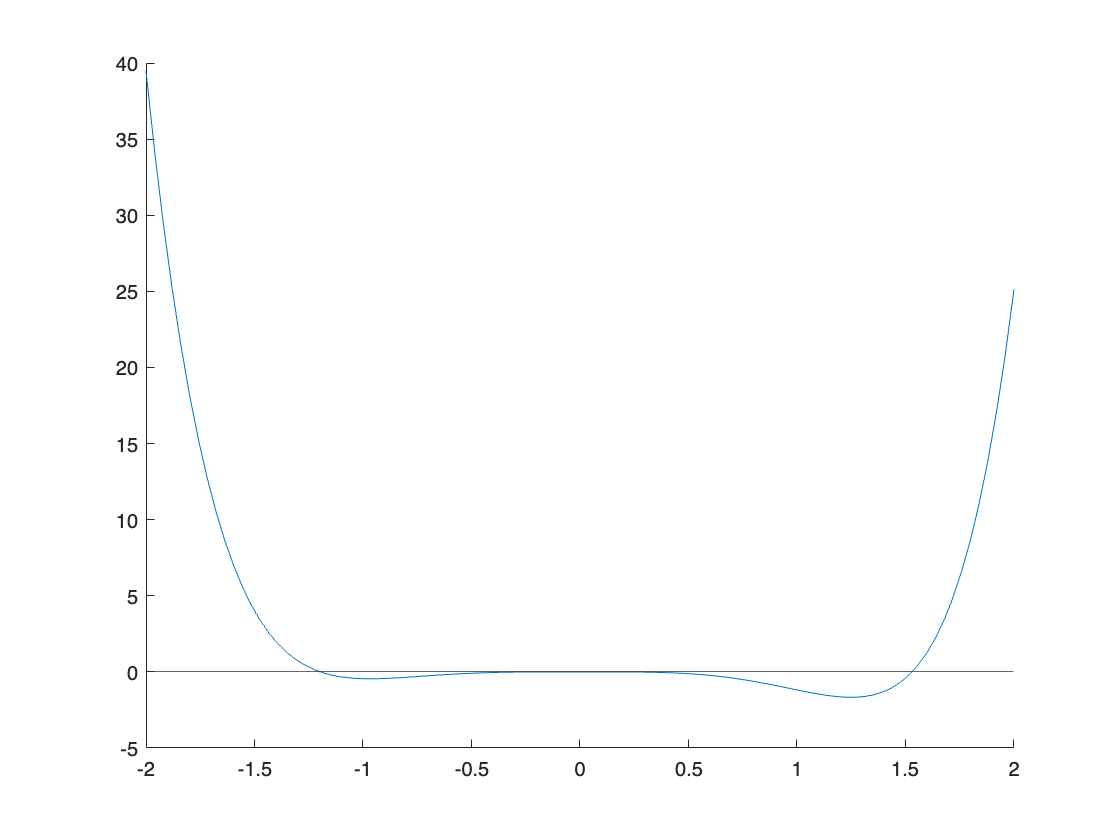

yline(0) %make it easy to see x-axis
hold on 
% Start your code below 
x = linspace(-2,2,100);
plot(x,f(x));

**c)** Define an anonymous function for $f'(x)$. You can find the derivative analytically and then define the function.

df = @(x) 3*sin(x)*cos(x).^2*exp(sin(x).^3) + 6*x.^5 - 8*x.^3 - 3*x.^2;


**d) **Find all the roots of $f(x)$ to within $10^{-8}$ using Newton's method. Use $\texttt{newton.m}$ provided. Choose an arbitrary number of maximum iterates that you think will be sufficient. Pick a good starting guess that's not the root itself. Recall from class what a good guess for Newton's Method is. You might have to experiment with different initial guess to make sure you get all the roots. *(Do not suppress output of your function call)*

p0 = -2;
Nmax = 20;
tol = 10e-8;
x1 = newton(f,df,p0,Nmax,tol)

i =    0, p = -2.0000000000e+00
i =    1, p = -1.718508544248844e+00
i =    2, p = -1.499153299651871e+00
i =    3, p = -1.340996699050913e+00
i =    4, p = -1.246072459133151e+00
i =    5, p = -1.207419128815046e+00
i =    6, p = -1.198876786558719e+00
i =    7, p = -1.197761044711774e+00
i =    8, p = -1.197638434656236e+00
i =    9, p = -1.197625294435267e+00
i =   10, p = -1.197623890117180e+00
i =   11, p = -1.197623740080301e+00
i =   12, p = -1.197623724050925e+00


x1 =   -1.197623724050925


p0 = 1e-3;
x2 = newton(f,df,p0,Nmax,tol)

i =    0, p = 1.0000000000e-03
i =    1, p = 1.000000667507021e-03


x2 =    0.001000000667507


p0 = 2;
x3 = newton(f,df,p0,Nmax,tol)

i =    0, p = 2.0000000000e+00
i =    1, p = 1.785295229585333e+00
i =    2, p = 1.638959256744559e+00
i =    3, p = 1.557842166792997e+00
i =    4, p = 1.532106180985709e+00
i =    5, p = 1.530105367172348e+00
i =    6, p = 1.530134119252582e+00
i =    7, p = 1.530133494962773e+00
i =    8, p = 1.530133508451944e+00


x3 =    1.530133508451944


**e)** From your results above, does it look like Newton's method converges linearly or quadratically to each of the roots? Remember quadratic convergence is faster than linear convergence.

**Your answer as text below: **

Look's like Newton's method converges quadratically to each of the roots (converges really fast, especially compared to other methods such as the Bisection method which take more iterations for less accuracy, e.g., in Lab 2 the Bisection method took 20 iterations to converge at $10^{-6}$ accuracy whereas Newton's method takes at most$10 \pm 2$ iterations to converge at $10^{-8}$ accuracy).

**Problem 2**

In a separate file, create a function that implements the Secant Method. Then solve $e^x + x = 7$ to within $10^{-6}$ using the Secant Method. Your must print out the approximations at each step like the provided Newton's Method code. Here is the first line of your function:

The outputs are: $p$ the solution and $i$ the number of steps it takes to get a solution. The inputs are: $p0 = 1$ and $p1 = 2$ the two initial guesses, $Nmax$ the maximum number of iterations allowed, $tol$ the accuracy tolerance.

p0 = 1;
p1 = 2;
f = @(x) exp(x) + x - 7;
tol = 10e-6;
x0 = secant(f,p0,p1,Nmax,tol)

i =    1, p = 1.0000000000e+00
i =    2, p = 1.578707247902504e+00
i =    3, p = 1.660160099942699e+00
i =    4, p = 1.673327962212480e+00
i =    5, p = 1.672818997263296e+00
i =    6, p = 1.672821698053204e+00


x0 =    1.672821698053204
